1) Load barcode data

%load('C:\Users\Lenovo\postdoc\DATA\TEMP\3_2023-11-22_11_34_44resRun.mat', "bG"); 
load('/export/scratch/albertas/data_temp/bargrouping/PAPER_DATA/3_2023-11-22_11_34_44resRun.mat', "bG");


Choose a dataset to work with

% dataIdx = 1;
% barcodeGen = bG{dataIdx};
for dataIdx = 1:length(bG)
    try
        [expPar{dataIdx}.nmbp, expPar{dataIdx}.nmpx] = Input.extract_extension_params(fileparts(bG{dataIdx}{1}.name));
    catch
        expPar{dataIdx}.nmpx = 110;
        expPar{dataIdx}.nmbp = 0.25;
    end
    fastaFileF{dataIdx} ='/export/scratch/albertas/data_temp/bargrouping/ecoli/FASTAS/DA32087.fasta';
end



2) Theory. All parameters

% default parameters
sF = 0.9:0.025:1.1; % length re-scaling parameter
sets.nuF = 0.08; sets.nF = 0.2; % pval params 
sets.comparisonMethod = 'mass_pcc'; % could use C++ version or UCR ED as well
sets.w = nan;

sigma = 0.68;
gcSF  = 1; % gc re-scaling (todo - calculate estimated number of ligands per pixel)
kY = 10; % constant yoyo
kN = 60; % constant netropsin
psf = 370; % psf
cN = 6; % concentration netropsin
cY = 0.02; % concentration yoyo
% pxSize = nmpx/nmbp; % pixel size
ligandLength = 4; % ligand length
isC = 1; % whether circular

% parlist = [gcSF,pxSize,nmpx,isC,sigma,kN,psf,cY,cN,kY,ligandLength];
% parlistcell = num2cell(parlist) ;
[hcaSets,timestamp] = set_def();
hcaSets.folder{1} = {'/export/scratch/albertas/data_temp/bargrouping/ecoli/FASTAS/DA32087.fasta'};

Pre-calculate best position for each 

yoyo = 26;
netrospin = 0.4;
parchangeId = 5; % scaling factor for binding constants
par = 0.68;%

mA = zeros(1,length(bG));
sA = zeros(1,size(twoList,1));
mtwo= zeros(1,size(twoList,1));
sttwo= zeros(1,size(twoList,1));
mps= zeros(1,length(bG));
allCoefsHCA = cell(1,length(bG));
allCoefsFit = cell(1,length(bG));

bI = {};
cI = {};
hc = {};
parl = {};
for expNr = 1:length(bG)
    expNr
    barcodeGen = bG{expNr};

    % params
    nmbp = expPar{expNr}.nmbp;
    nmpx = expPar{expNr}.nmpx;
    hcaSets.pixelWidthNm = nmpx;
    hcaSets.folder = {fastaFileF{expNr}} ;    
    pxSize = nmpx/nmbp; % pixel size
    parlist = [gcSF,pxSize,nmpx,isC,sigma,kN,psf,cY,cN,kY,ligandLength];
    parlistcell = num2cell(parlist) ;

    hcaSets.pattern = 'binding_constant_rules.txt';
    hcaSets.method = 'literature';
    import Core.run_hca_theory;
    hcaTheory = arrayfun(@(x) run_hca_theory(hcaSets,x,netrospin),yoyo,'un',false);
    [compI2,rezI2,m2(expNr),st2(expNr)] = run_comp(barcodeGen,hcaTheory,nmbp,sets,sF);

    
    stoufferScoresL = cellfun(@(x) double(norminv(1-x.pval)),compI2,'un',true);
    
    mAll = cellfun(@(y) cellfun(@(x) x.maxcoef(1),y), rezI2,'un',false);
    
    idx  = find(stoufferScoresL > 1.44);

    allCoefsHCA{expNr} = cellfun(@(x) x.maxcoef(1),compI2(idx));

expNr = 1

Computing free concentrations
Elapsed time is 0.868709 seconds.
Finished computing free concentrations
loaded theory sequence /export/scratch/albertas/data_temp/bargrouping/ecoli/FASTAS/DA32087.fasta
Finished calculating theories


Elapsed time is 2.278510 seconds.


expNr = 2

Computing free concentrations
Elapsed time is 0.882739 seconds.
Finished computing free concentrations
loaded theory sequence /export/scratch/albertas/data_temp/bargrouping/ecoli/FASTAS/DA32087.fasta
Finished calculating theories


Elapsed time is 1.593577 seconds.


expNr = 3

Computing free concentrations
Elapsed time is 0.850247 seconds.
Finished computing free concentrations
loaded theory sequence /export/scratch/albertas/data_temp/bargrouping/ecoli/FASTAS/DA32087.fasta
Finished calculating theories


Elapsed time is 0.908796 seconds.


expNr = 4

Computing free concentrations
Elapsed time is 0.858438 seconds.
Finished computing free concentrations
loaded theory sequence /export/scratch/albertas/data_temp/bargrouping/ecoli/FASTAS/DA32087.fasta
Finished calculating theories


Elapsed time is 1.284438 seconds.


expNr = 5

Computing free concentrations
Elapsed time is 0.848694 seconds.
Finished computing free concentrations
loaded theory sequence /export/scratch/albertas/data_temp/bargrouping/ecoli/FASTAS/DA32087.fasta
Finished calculating theories


Elapsed time is 1.933881 seconds.


expNr = 6

Computing free concentrations
Elapsed time is 0.846840 seconds.
Finished computing free concentrations
loaded theory sequence /export/scratch/albertas/data_temp/bargrouping/ecoli/FASTAS/DA32087.fasta
Finished calculating theories


Elapsed time is 2.462488 seconds.


expNr = 7

Computing free concentrations
Elapsed time is 0.842920 seconds.
Finished computing free concentrations
loaded theory sequence /export/scratch/albertas/data_temp/bargrouping/ecoli/FASTAS/DA32087.fasta
Finished calculating theories


Elapsed time is 4.580100 seconds.


expNr = 8

Computing free concentrations
Elapsed time is 0.844691 seconds.
Finished computing free concentrations
loaded theory sequence /export/scratch/albertas/data_temp/bargrouping/ecoli/FASTAS/DA32087.fasta
Finished calculating theories


Elapsed time is 1.979709 seconds.


expNr = 9

Computing free concentrations
Elapsed time is 0.855994 seconds.
Finished computing free concentrations
loaded theory sequence /export/scratch/albertas/data_temp/bargrouping/ecoli/FASTAS/DA32087.fasta
Finished calculating theories


Elapsed time is 2.920853 seconds.


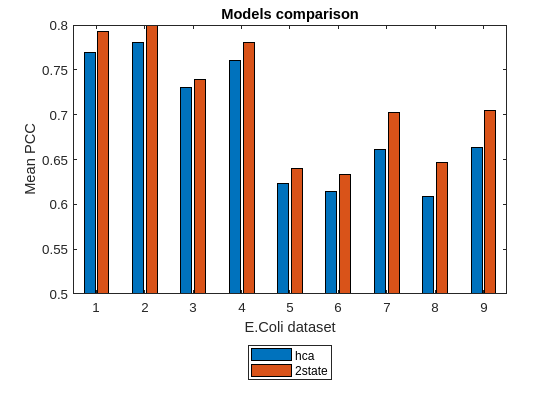


    mA(expNr) = mean(mAll{1}(idx));
    sA(expNr) = std(mAll{1}(idx));
    
    bI{expNr} = barcodeGen(idx);
    parl{expNr} = parlistcell;
    hc{expNr} = hcaSets.folder{1};

  [~,mid,~] = fileparts(hcaSets.folder );
delete(['seq_example',mid,'_',num2str(ligandLength) ,'.mat']);

    import Helper.run_comparison_fit;

    [cI{expNr}, rezI,   mtwo(expNr) , sttwo(expNr), sS, theoryStr, yoyoBindingProb, netropsinBindingConst] = ...
        run_comparison_fit( bI{expNr},hcaSets.folder{1},parlistcell{:},parchangeId,par,sF,sets);
    allCoefsFit{expNr} = cI{expNr}.maxcoef;
end

mtwo = cellfun(@(x) mean(x.maxcoef),cI,'UniformOutput',true);

% Comparison plot
lengths = cellfun(@(x) length(x),bI);
figure,bar([mA(1:length(bG));mtwo(1:length(bG))]')
hold on
title('Models comparison')
legend({'hca','2state'},'location','southoutside')
xlabel('E.Coli dataset')
ylabel('Mean PCC')
ylim([0.5 0.8])

% exportgraphics(f,'outfig_ecoli.png', 'Resolution',500)

% expNr = 9;
% d = [allCoefsHCA{expNr} allCoefsFit{expNr}]';
% 
% group_inx = [ones(1,length(allCoefsHCA{expNr})) 2*ones(1,length(allCoefsFit{expNr}))];
% 
% %%
% figure;%('Name', 'daviolinplot_demo','WindowStyle','docked');
% 
% 
% h = daviolinplot(d,'groups',group_inx,'outsymbol','k+',...
%     'boxcolors','w','violin','full','scatter',1,'jitter',1,'xtlabels', {'A','B'},...
%     'legend',{'G1','G2'});
% 
% ylabel('Performance');
% xl = xlim; xlim([xl(1)-0.1, xl(2)+0.2]); % make more space for the legend
% set(gca,'FontSize',10);


3) Fit one of the parameters by running through the list of parameters

expNr = 6;
barcodeGen = bI{expNr};

% params
nmbp = expPar{expNr}.nmbp;
nmpx = expPar{expNr}.nmpx;
hcaSets.pixelWidthNm = nmpx;
hcaSets.folder = fastaFileF{expNr} ;    
pxSize = nmpx/nmbp; % pixel size

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         257   -7.113165e-01     0.000e+00     1.000e+00     0.000e+00     2.633e-02  
    1         514   -7.150770e-01     0.000e+00     1.000e+00     1.232e-01     4.436e-02  
    2         771   -7.173423e-01     0.000e+00     1.000e+00     9.595e-02     8.277e-02  
    3        1029   -7.202581e-01     0.000e+00     7.000e-01     1.168e-01     3.667e-02  
    4        1286   -7.254880e-01     0.000e+00     1.000e+00     6.824e-02     1.649e-02  
    5        1543   -7.276526e-01     0.000e+00     1.000e+00     8.735e-02     1.746e-02  
    6        1800   -7.296152e-01     0.000e+00     1.000e+00     6.435e-02     8.953e-03  
    7        2057   -7.312002e-01     0.000e+00     1.000e+00     1.238e-01     1.556e-02  
    8        2314   -7.320895e-01     0.000e+00     1.000e+00     4.408e-02     1.

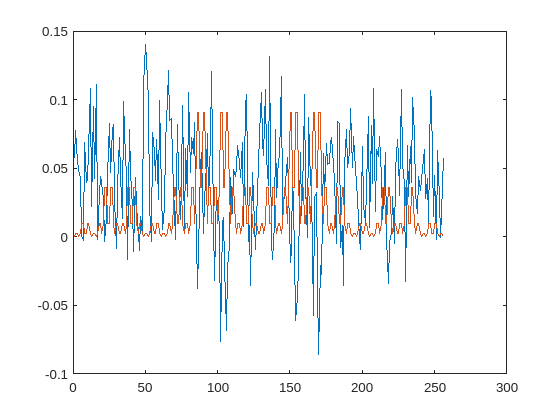

parlist = [gcSF,pxSize,nmpx,isC,sigma,kN,psf,cY,cN,kY,ligandLength];
parlistcell = num2cell(parlist) ;

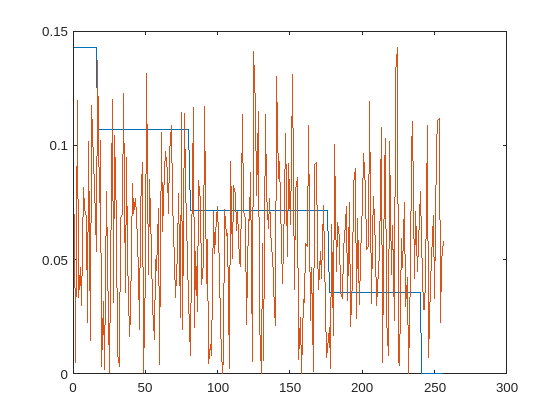


% run comparison, change gcSF
% import Helper.run_comparison;
parchangeId = 5; % scaling factor for binding constants

% par = 0.5;%
par = [0.5];

ZZ =     0.0582    0.0798    0.0573    0.0497    0.0450    0.0110    0.0071    0.0709    0.0417    0.0514    0.0739    0.1106    0.0227    0.0976    0.0448    0.1118    0.0002    0.0417    0.0537    0.0423    0.0370    0.0323    0.0501    0.0551    0.0925    0.0828    0.1141    0.0916    0.0295    0.0012    0.0465    0.0749    0.0465    0.0232    0.1087    0.0594    0.0559    0.0196    0.1144    0.0570    0.0312    0.0249    0.0790    0.0326    0.0037    0.0000    0.0247    0.0061    0.1109    0.1427




  [~,mid,~] = fileparts(hcaSets.folder );
delete(['seq_example',mid,'_',num2str(ligandLength) ,'.mat']);

import Helper.run_comparison_fit;
[compI, ~, m, st, sS,theoryStr,yoyoBindingProb] = run_comparison_fit(barcodeGen,hcaSets.folder,parlistcell{:},parchangeId,par,sF,sets);

figure,plot(par,m)
xlabel('$\sigma$','Interpreter','latex')
ylabel('PCC','Interpreter','latex')
hold on



Parameter fit

expNr = 1

expNr = 2

expNr = 3

expNr = 4

expNr = 5

expNr = 6

expNr = 7

expNr = 8

expNr = 9

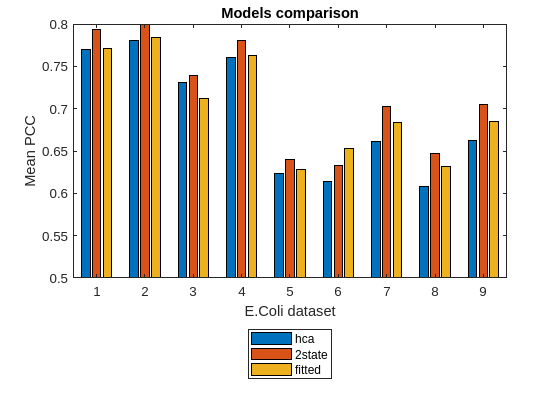


import Core.rescale_barcode_data; % re-scale initial data
[barGenRe] = rescale_barcode_data(barcodeGen,1,compI.bestBarStretch);


data = load('seq_exampleDA32087_4.mat');
tic;[m] = constfun_fit(yoyoBindingProb,compI,barGenRe,data,parlistcell,sets);toc

nvars = length(yoyoBindingProb);

fun = @(xSv) -constfun_fit(xSv, compI,barGenRe,data,parlistcell,sets);


SQP

tol = 1e-11;
options_all = optimoptions(@fmincon,'Display', 'iter', 'Algorithm', 'sqp', 'SpecifyObjectiveGradient',false, 'CheckGradient', false,  'OptimalityTolerance', tol, 'MaxFunctionEvaluations',20000 , 'StepTolerance', tol);

xopt = [yoyoBindingProb];

lbounds = [zeros(1, nvars)];
ubounds = [0.3*ones(1, nvars)]; % no upper bounds on amplitudes

[ZZ,FVAL,EXITFLAG,OUTPUT] = fmincon(@(x) fun(x), xopt, [], [], [], [], lbounds, ubounds, [], options_all);

figure,plot([ZZ-xopt]);hold on;plot(xopt)
        [sortedSubseq, sortv, countATs, orderSeq,sortord] = sorted_NT(ligandLength);

        figure,plot(sortv*max(ZZ)/4);hold on
        plot(ZZ(fliplr(sortord)))

        ZZ


averageCC = zeros(1,length(bG));
for expNr = 1:length(bG)
    expNr
    barcodeGen = bI{expNr} ;

    % params
    nmbp = expPar{expNr}.nmbp;
    nmpx = expPar{expNr}.nmpx;
    hcaSets.pixelWidthNm = nmpx;
    hcaSets.folder = fastaFileF{expNr} ;    
    pxSize = nmpx/nmbp; % pixel size
    parlist = [gcSF,pxSize,nmpx,isC,sigma,kN,psf,cY,cN,kY,ligandLength];
    parlistcell = num2cell(parlist) ;

    
    import Core.rescale_barcode_data; % re-scale initial data
    [barGenRe] = rescale_barcode_data(barcodeGen,1,cI{expNr}.bestBarStretch);

    [~,mid,~] = fileparts(hcaSets.folder );
    delete(['seq_example',mid,'_',num2str(ligandLength) ,'.mat']);

%     [averageCC(expNr)] = constfun_fit(ZZ,cI{expNr},barGenRe,hcaSets.folder,parlistcell,sets);
        [averageCC(expNr)] = constfun_fit(ZZ,[],barGenRe,hcaSets.folder,parlistcell,sets);


end

lengths = cellfun(@(x) length(x),bI);
figure,bar([mA(1:length(bG));mtwo(1:length(bG));averageCC]')
hold on
title('Models comparison')
legend({'hca','2state','fitted'},'location','southoutside')
xlabel('E.Coli dataset')
ylabel('Mean PCC')
ylim([0.5 0.8])

% exportgraphics(f,'outfig_ecoli.png', 'Resolution',500)


fun(yoyoBindingProb)

% % genetic
% [bestxSv, fval] = ga(fun, nvars);

xopt = [yoyoBindingProb];

idX = 9;
vals = 0:0.01:0.2;
outv = zeros(1,numel(vals));
for i=1:numel(vals)
    xopt(idX) = vals(i);
    outv(i) = fun(xopt);
end

figure,plot(vals,outv,'x-')
hold on
plot([yoyoBindingProb(idX) yoyoBindingProb(idX)],[min(outv) max(outv)],'red-')
title('Single par. fit')



%% SQP?

tol = 1e-11;
options_all = optimoptions(@fmincon,'Display', 'iter', 'Algorithm', 'sqp', 'SpecifyObjectiveGradient',false, 'CheckGradient', false,  'OptimalityTolerance', tol, 'MaxFunctionEvaluations',3000 , 'StepTolerance', tol);
% xopt(1)=3;
% options_all= optimoptions(@fmincon,'Display', 'off', 'Algorithm', 'active-set', 'SpecifyObjectiveGradient',false, 'CheckGradient', false,  'OptimalityTolerance', tol, 'MaxFunctionEvaluations', 1e3, 'StepTolerance', tol);

xopt = [yoyoBindingProb];

fun(xopt)
% [ZZ] = fmincon(@(x) fun(x), xopt, [], [], [], [], lbounds, ubounds, [],options_all);

%%
% no bounds ...
lbounds = [zeros(1, nvars)];
ubounds = [0.3*ones(1, nvars)]; % no upper bounds on amplitudes


[ZZ] = fmincon(@(x) fun(x), xopt, [], [], [], [], lbounds, ubounds, [], options_all);

figure,plot([ZZ-xopt]);hold on;plot(xopt)
        [sortedSubseq, sortv, countATs, orderSeq,sortord] = sorted_NT(ligandLength);

        figure,plot(sortv*max(ZZ)/4);hold on
        plot(ZZ(fliplr(sortord)))

        ZZ


As test, use the next bG

dataIdx2 = 9;
barcodeGen2 = bG{dataIdx2};
[nmbp2, nmpx2] = Input.extract_extension_params(fileparts(bG{dataIdx2}{1}.name));

parchangeId = 5; % scaling factor for binding constants
par = 0.5;%
% par = [0.4:0.01:0.8];

import Helper.run_comparison_fit;
[compI2, rezI2, m2, st2, sS2,theoryStr2,yoyoBindingProb2] = run_comparison_fit(barcodeGen2,hcaSets.folder{1},parlistcell{:},parchangeId,par,sF,sets);
fun2 = @(xSv) -constfun_fit(xSv, compI2,barcodeGen2,fastaFile,parlistcell,sF,sets);
m2Test = fun2(ZZ);
[m2 -m2Test]

Particle swarm

options = optimoptions('particleswarm','SwarmSize',50);%,'HybridFcn',@fmincon);
rng default  % For reproducibility

% [x,fval,exitflag,output,points] = particleswarm(@(x) fun(x),nvars, lbounds, ubounds,options)

[x,fval,exitflag,output] = particleswarm(@(x) fun(x),nvars, lbounds, ubounds,options)


% fun = @(x)x(1)*exp(-norm(x)^2);
% lb = [-10,-15];
% ub = [15,20];
% options = optimoptions('particleswarm','SwarmSize',50,'HybridFcn',@fmincon);
% rng default  % For reproducibility
% nvars = 2;
% [x,fval,exitflag,output,points] = particleswarm(fun,nvars,lb,ub,options)